load("tiremax.mat") %array of tire data for normal forces and their corresponding tire longitudinal forces

% Constants
Xf = 0.768; % m, distance between center of gravity and front axle, 0.808 for MY24
Xr = 0.756; % m, distance between center of gravity and rear axle, 0.716 for MY24
Ycg = 0.254; % m, distance between center of gravity and ground, 0.3129
g = 9.8; % m/s^2, acceleration due to gravity
m = 273.32; % m, mass allocation of the car with driver
tireRad = 0.2032; % m, radius of the tires
rotorRad = 0.0889; % m, PLACEHOLDER radius of caliper
idealPedalForce = 1000; % N, ideal force the driver must push with to exert ideal brake pressure

% Wilwood GP200 Properties
muCalipGP200 = 0.32; % unitless, estimated coefficient of friction for our brake pads
pistonAreaGP200 = 0.0007935468; % m^2, piston area for Wilwood GP200
pistonCountGP200 = 2; 

% Wilwood PS1 Properties
muCalipPS1 = 0.4; % unitless
pistonAreaPS1 = 0.00064516; % m^2
pistonCountPS1 = 2;

% AP Racing CP3696-6E0 Properties
muCalip3696 = 0.45; % unitless
pistonArea3696 = 0.00267; % m^2
pistonCount3696 = 2;

% AP Racing CP4226-2S0 Properties
muCalip4226 = 0.39; % unitless
pistonArea4226 = 0.00101; % m^2
pistonCount4226 = 2;

% ISR 22-027 Properties
muCalip027 = 0.35; % APPROXIMATION, NO DATA AVAILABLE
pistonArea027 = 0.000908;
pistonCount027 = 2;

% ISR 22-043 Properties
muCalip043 = 0.4;
pistonArea043 = 0.0004909;
pistonCount043 = 4;

% ISR 22-047 Properties
muCalip047 = 0.35; % APPROXIMATION, NO DATA AVAILABLE
pistonArea047 = 0.000908;
pistonCount047 = 4;

% ISR 22-048 Properties
muCalip048 = 0.4;
pistonArea048 = 0.0004909;
pistonCount048 = 4;

% Brembo Properties
muCalipBrembo = 0.4;
pistonAreaBrembo = 0.0008042;
pistonCountBrembo = 2;

% Tilton Racing 78 Properties
boreDiametersTilton = [13/16,15/16,3/4,5/8,7/10,7/8,1]./39.37; % m, bore diameter options for master cylinder

% AP Racing CP2623 MC Properties
boreDiameters2623 = [14,15,15.9,16.8,17.8,19.1,20.6,22.2,23.8,25.4].*.001; % m, bore diameter options for master cylinder

% AP Racing CP4400 MC Properties
boreDiameters4400 = [14,15,15.9,16.8,17.8,19.1,20.6,22.2,23.8].*.001; % m, bore diameter options for master cylinder


% Variables
noRotAccel = [0.0]; % Array of acceleration values calculated by a balance of moments
forceAccel = [0.0]; % Array of acceleration values calculated by F = ma
aMax = 0.0; % Acceleration value that maximizes both F=ma and maintains a balance of moments
rOptimal = 0.0; % Optimal front weight bias that produces maximum acceleration

% Tire data arrays
longitudinal_force = values(2, :); % stores all the values of longitudinal tire force with respect to an input normal force
normal_force = values(1,:); % stores all the values of normal force to associate with longitudinal force

% Iterate through values of front weight bias to find a list of
% accelerations through both moment balance and F = ma
vals = linspace(0, 1, 1000);
noRotAccel = zeros(1, length(vals));
forceAccel = zeros(1, length(vals));
for i = 1:length(vals)
    r = vals(i);
    noRotAccel(i) = (Xf*g*r - (Xr*g*(1-r)))/Ycg;
    forceAccel(i) = (2/m)*(interp1(-normal_force,longitudinal_force, (m*g*r)/2,"pchip")+interp1(-normal_force,longitudinal_force, (m*g*(1-r))/2,"pchip"));
end
% Interpolates both F=MA and No Rotation graphs to allow the intersection point to be found
forceAccelInt = griddedInterpolant(vals,forceAccel);
noRotAccelInt = griddedInterpolant(vals,noRotAccel);
diff = @(x) forceAccelInt(x) - noRotAccelInt(x);
rOptimal = fzero(diff,1)

rOptimal = 0.7614

% Calculates the maximum acceleration possible with the ideal Front/Rear bias ratio
aMax = (Xf*g*rOptimal - (Xr*g*(1-rOptimal)))/Ycg;

% Defines rF (front brake bias) and rOptim (ideal F/R ratio) as symbolic variables, then defines an equation to solve for rF given rOptim
syms rF rOptim
eqn = rF / (1-rF) == rOptim;
% Solves the above equation for the desired rear bias
rearBias = double(solve(subs(eqn, rOptim, rOptimal), rF))

rearBias = 0.4323

frontBias = double(1-rearBias)

frontBias = 0.5677

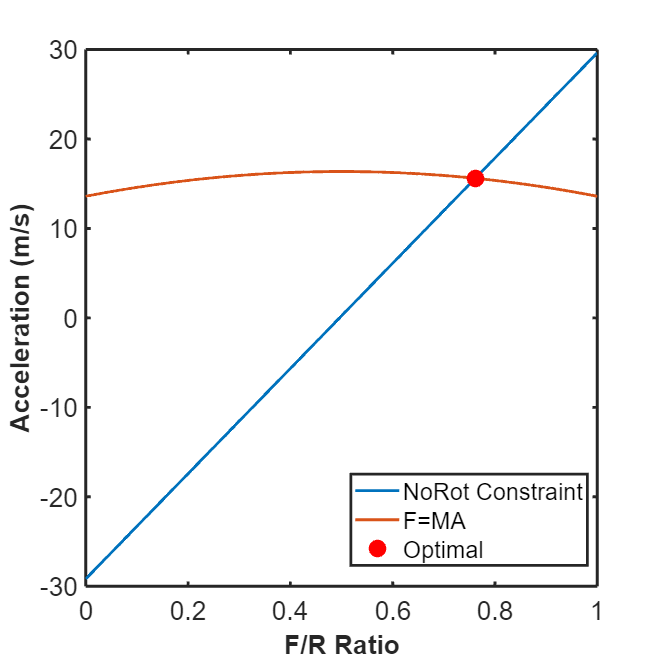


% Plot the No Rotation constraint and F=MA acceleration to find the intersection point
figure; hold on
plot(vals, noRotAccel, "DisplayName", "NoRot Constraint")
plot(vals, forceAccel, "DisplayName", "F=MA")
plot(rOptimal,aMax,"ro", "DisplayName", "Optimal")
xlabel("F/R Ratio")
ylabel("Acceleration (m/s)")
legend("Position", [0.5881,0.23413,0.25714,0.11905])
improvePlot


% Calculate the longitudinal force of a single tire for both the front and the rear
longForceFront = interp1(-normal_force,longitudinal_force,(m*g*frontBias)/2,"pchip");
longForceRear = interp1(-normal_force,longitudinal_force,(m*g*rearBias)/2,"pchip");

% Calculate the torque on the wheel from the longitudinal force on the tire and the radius of the wheel
wheelTorqueFront = longForceFront * tireRad;
wheelTorqueRear = longForceRear * tireRad;

% Calculate the necessary caliper force to produce a torque equal to the tires given a certain rotor radius
forceCalFront = wheelTorqueFront/rotorRad;
forceCalRear = wheelTorqueRear/rotorRad;

% Set up and solve an equation to convert the necessary caliper force to a line pressure using the caliper's pad coefficient of friction and piston area (assumes 2 pistons)
syms calForce LP
eqn = @(pistonArea, pistonCount, muCalip) calForce == LP*pistonCount*pistonArea*muCalip;

% GP200 Line Pressures in Pa
linePressureFrontGP200 = double(solve(subs(eqn(pistonAreaGP200, pistonCountGP200, muCalipGP200), calForce, forceCalFront),LP))/6895;
linePressureRearGP200 = double(solve(subs(eqn(pistonAreaGP200, pistonCountGP200,muCalipGP200), calForce, forceCalRear),LP))/6895

linePressureRearGP200 = 645.2930


% PS1 Line Pressures in Pa
linePressureFrontPS1 = double(solve(subs(eqn(pistonAreaPS1, pistonCountPS1, muCalipPS1), calForce, forceCalFront),LP))/6895;
linePressureRearPS1 = double(solve(subs(eqn(pistonAreaPS1, pistonCountPS1, muCalipPS1), calForce, forceCalRear),LP))/6895;

% AP Racing CP3696-6E0 Line Pressures in Pa
linePressureFront3696 = double(solve(subs(eqn(pistonArea3696, pistonCount3696, muCalip3696), calForce, forceCalFront),LP))/6895;
linePressureRear3696 = double(solve(subs(eqn(pistonArea3696, pistonCount3696, muCalip3696), calForce, forceCalRear),LP))/6895;

% AP Racing CP4226-2S0 Line Pressures in Pa
linePressureFront4226 = double(solve(subs(eqn(pistonArea4226, pistonCount4226, muCalip4226), calForce, forceCalFront),LP))/6895

linePressureFront4226 = 521.8750

linePressureRear4226 = double(solve(subs(eqn(pistonArea4226, pistonCount4226, muCalip4226), calForce, forceCalRear),LP))/6895;

% ISR 22-027 Properties
linePressureFront027 = double(solve(subs(eqn(pistonArea027, pistonCount027, muCalip027), calForce, forceCalFront),LP))/6895;
linePressureRear027 = double(solve(subs(eqn(pistonArea027, pistonCount027, muCalip027), calForce, forceCalRear),LP))/6895;

% ISR 22-043 Properties
linePressureFront043 = double(solve(subs(eqn(pistonArea043, pistonCount043, muCalip043), calForce, forceCalFront),LP))/6895;
linePressureRear043 = double(solve(subs(eqn(pistonArea043, pistonCount043, muCalip043), calForce, forceCalRear),LP))/6895;

% ISR 22-047 Properties
linePressureFront047 = double(solve(subs(eqn(pistonArea047, pistonCount047, muCalip047), calForce, forceCalFront),LP))/6895;
linePressureRear047 = double(solve(subs(eqn(pistonArea047, pistonCount047, muCalip047), calForce, forceCalRear),LP))/6895;

% ISR 22-048 Properties
linePressureFront048 = double(solve(subs(eqn(pistonArea048, pistonCount048, muCalip048), calForce, forceCalFront),LP))/6895;
linePressureRear048 = double(solve(subs(eqn(pistonArea048, pistonCount048, muCalip048), calForce, forceCalRear),LP))/6895;

% Brembo Properties
linePressureFrontBrembo = double(solve(subs(eqn(pistonAreaBrembo, pistonCountBrembo, muCalipBrembo), calForce, forceCalFront),LP))/6895;
linePressureRearBrembo = double(solve(subs(eqn(pistonAreaBrembo, pistonCountBrembo, muCalipBrembo), calForce, forceCalRear),LP))/6895;


% Compute bore areas of the different master cylinder options
boreArea = @(bd) pi.*(((bd)./2).^2); % Converts bore diameter to bore area
% Generate arrays of all bore areas for all 3 possible master cylinders, then adds them into one master array to iterate through
boreAreasTilton = boreArea(boreDiametersTilton); 
boreAreas2623 = boreArea(boreDiameters2623);
boreAreas4400 = boreArea(boreDiameters4400);
boreAreas = [boreAreasTilton boreAreas2623 boreAreas4400];
boreDiameterFromArea = @(ba) 2*(sqrt(ba/pi)); % Allows the diameter to be backed out from the area later so we can know what cylinder to choose

% Determines the optimal bore diameter combinations by iterating through every possible combination
biasRatioOptions = []; % Empty array to store all the possible bias ratios created by the bore combinations
MCcombosFront = []; % These two arrays are used to store the values of the front and rear bore used for each combo at the same index to allow them to be searched later
MCcombosRear = [];
for front = 1:length(boreAreas)
    for rear = 1:length(boreAreas)
        biasRatioOptions(end+1) = (boreAreas(front)/boreAreas(rear));
        MCcombosFront(end+1) = boreDiameterFromArea(boreAreas(front));
        MCcombosRear(end+1) = boreDiameterFromArea(boreAreas(rear));
    end
end

% Iterates through all the calculated ratio to find the one closest to the desired optimal ratio, then finds the front and rear bore diameters necessary to create that ratio
ratioDelta = []; % Will store all the distances between the calculated bias ratio and the desired ratio
for i = 1:length(biasRatioOptions)
    ratioDelta = abs(biasRatioOptions - rOptimal);
end
optimalRatioError = min(ratioDelta);
indexRealOptimalBoreRatio = find(ratioDelta==optimalRatioError);
optimalMCfront = MCcombosFront(indexRealOptimalBoreRatio) % m, optimal front bore diameter

optimalMCfront =     0.0222    0.0222


optimalMCrear = MCcombosRear(indexRealOptimalBoreRatio) % m, optimal rear bore diameter

optimalMCrear =     0.0254    0.0254
